## Datorövning 1 Numeraisk matematik, två cirklar

### Inledning

I denna raport löses följande uppgift:

"Två perfekt cirkelformade glasunderlägg,båda med samma radie **r** överlappar varandra som i bilden nedan, så att exakt halva ytan av det undre underlägget täcks av det övre. Var sker detta på cirklarna?"  Bilden under beskriver fenomenet. 

## 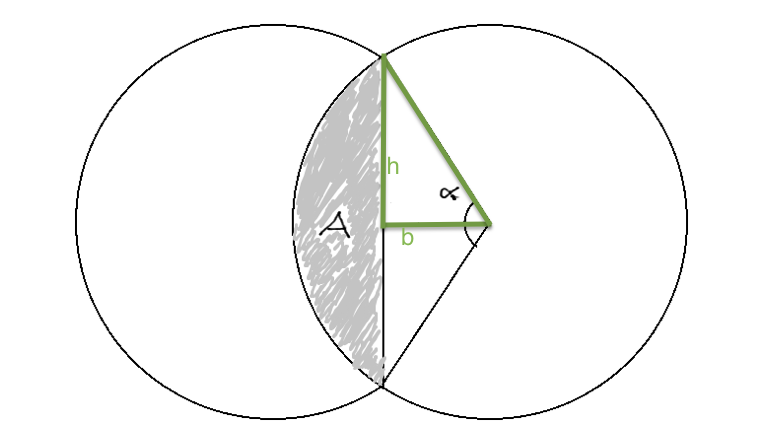

(Bild lånad av Mikael Kurula)

För att kunna undersöka problemet i Matlab så börjar vi med att visa att vinkeln $\alpha$ upfyller ekvationen $\alpha-sin{\alpha}=\frac{\pi}{2}$. Vi vet att arean av en cirkel sektor är $\frac{\alpha\pi r^2}{2\pi}$. Vi delar in tringeln (som skärs av de gråa området) i två rätvänkliga trianglar. Vi kallar höjden $h$ och basen $b$. Vi får då att att arean för $A = \frac{\alpha\pi r^2}{2\pi}-2\frac{hb}{2} = \frac{\alpha r^2}{2}-hb$ vi får med hjälp av trigonometsika samband att $h = r sin{\frac{\alpha}{2}$ och $b=rcos{\frac{\alpha}{2}}$.  Vi vet även att $A+A=\frac{\pi r^2}{2}$, alltså en halv cirkel area. När vi slår ihop dessa olika delar så får vi at $\frac{\pi r^2}{2}=2A=\alpha r^2-2hb=\alpha r^2-2(r sin{\frac{\alpha}{2}} -rcos{\frac{\alpha}{2})=\alpha r^2 -2r^2 sin{\frac{\alpha}{2}} cos{\frac{\alpha}{2}}$. Sedan använder vi oss av formeln sinus för dubblavinkeln, då får vi $\alpha r^2 -sin{\alpha}$. Alltså uppfyller vinkeln $\alpha
$ ekvationen om $r = 1$. Vi har nu kommit till $\alpha-sin{\alpha}=\frac{\pi}{2}$.

I nästa del kommer vi att beräkna $\alpha$ för att den övre cirkeln ska täcka exakt hälften av den nedra cirkeln.

### Beräkningar

Vi börjar med att rita funktionen y, som defineras som en dold funktion. Funktionens betende är även förtydligat med en bild. 

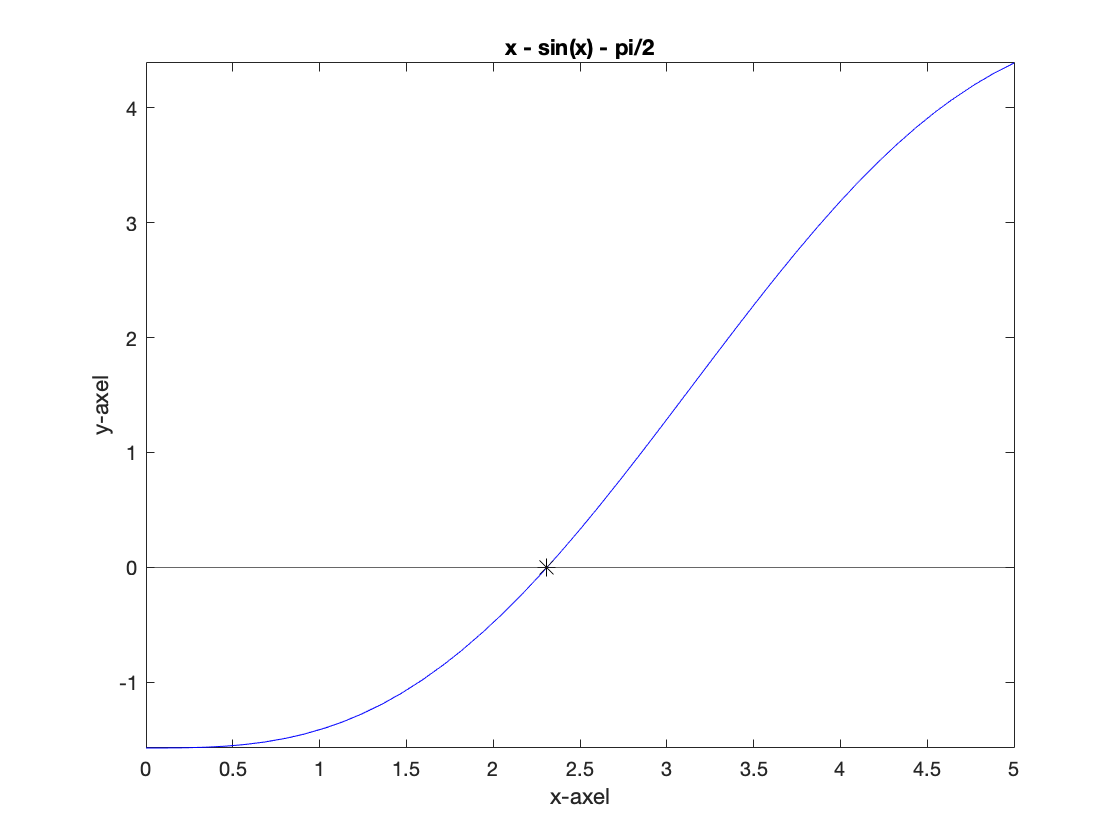

x = [0 5];
y = @(x) x - sin(x) - pi/2;
fplot(y,x,'b-') %ritar funktionen y
alfa_estimate = fzero(y,x);
hold on
plot(alfa_estimate,0,'k*',"MarkerSize",8) %ritar ut nollstället för alpha
yline(0);
xlabel('x-axel')
ylabel('y-axel')
title('x - sin(x) - pi/2')
hold off

Nollsätället $\alpha = 2,3099$ beskriver ett närmevärde.

options = optimset('Display','off'); %Räknar ut ett värde för alfa
alfa = fsolve(y,alfa_estimate,options)

alfa = 2.3099

Felet är nära noll så uppskattningen är en bra uppskattning. 

absolut_fel = y(alfa) 

absolut_fel = -4.4409e-16

### Slutsatser

Det finns bara en vinkel $\alpha$ som löser ekvationen $\alpha-sin{\alpha}=\frac{\pi}{2}$. Värdet på denna vinkel $\alpha$ är cirka 2.3099 radianer. Variabelns absoluta fel visar hur mycket värdet på $\alpha$ avviker från den exakta storheten. Variabelns absoluta fel är mycket litet vilket betyder att vårt $\alpha$ ligger mycket nära den exakta storheten och $\alpha-sin{\alpha}-\frac{\pi}{2}$ mycket nära 0. Då målet är att den övre cirkeln ska täcka hälften av den nedra ska man välja vinkel $\alpha$ så att den är 2.3099 radianer.